
ts = out.ScopeData1{1}; 

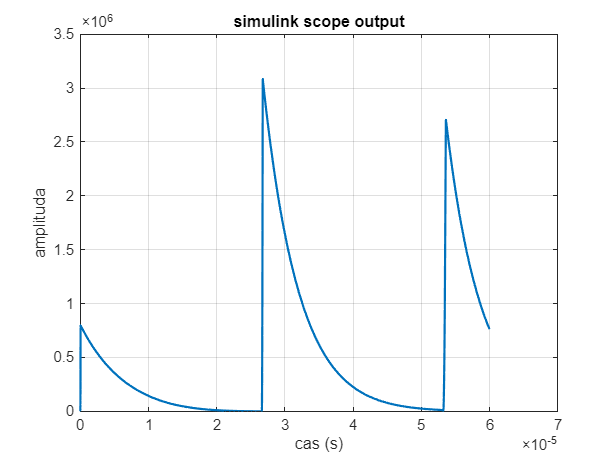

figure;
plot(ts.Values.Time, ts.Values.Data, 'LineWidth', 1.5);
xlabel('cas (s)');
ylabel('amplituda');
title('simulink scope output');
grid on;

time = ts.Values.Time; 

Unable to resolve the name 'ts.Values.Time'.

data = ts.Values.Data; 

indices = (time >= 0.000) & (time <= 2.5e-5);
integral_value = trapz(time(indices), data(indices))
watt_hours = integral_value/3600

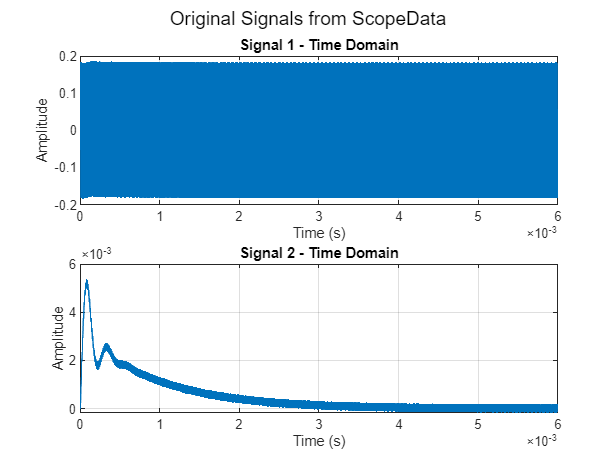

% --- Step 1: Extract Data from the SimulationOutput Object ---

% Assumes the 'out' object is in your workspace.
signal1_timeseries = out.new_var{1}.Values;
signal2_timeseries = out.new_var{2}.Values;

% Extract the data and time arrays.
data1 = signal1_timeseries.Data;
data2 = signal2_timeseries.Data;
time_vector = signal1_timeseries.Time;

% Ensure data is in column vector format.
data1 = data1(:);
data2 = data2(:);


% --- Step 2: Plot Original Signals (Time Domain) ---

% Create the first figure window for the time-domain plots.
figure(1); % Using figure(1) gives it a specific handle

% Create the first subplot for Signal 1 vs. Time.
subplot(2, 1, 1);
plot(time_vector, data1);
title('Signal 1 - Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Create the second subplot for Signal 2 vs. Time.
subplot(2, 1, 2);
plot(time_vector, data2);
title('Signal 2 - Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

sgtitle('Original Signals from ScopeData');

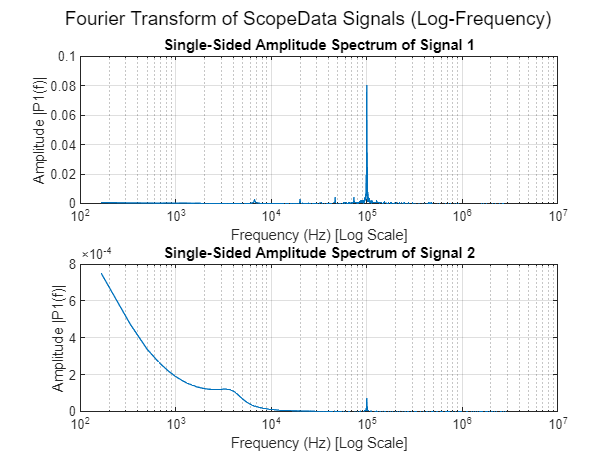

% --- Step 3: Define FFT Parameters ---
% This part remains the same.
Fs = 1 / mean(diff(time_vector));
L = length(time_vector); 


% --- Step 4: Compute the FFT for Both Signals ---
% This part remains the same.
f = Fs*(0:(L/2))/L;

Y1 = fft(data1);
P2_1 = abs(Y1/L);
P1_1 = P2_1(1:floor(L/2)+1);
P1_1(2:end-1) = 2*P1_1(2:end-1);

Y2 = fft(data2);
P2_2 = abs(Y2/L);
P1_2 = P2_2(1:floor(L/2)+1);
P1_2(2:end-1) = 2*P1_2(2:end-1);


% --- Step 5: Plot the FFT Results (Logarithmic X-Axis) ---

% Create a second figure window for the frequency-domain plots.
figure(2); 

% Create the first subplot for the FFT of Signal 1.
subplot(2, 1, 1);
% KEY CHANGE: Use semilogx instead of plot
semilogx(f, P1_1); 
title('Single-Sided Amplitude Spectrum of Signal 1');
xlabel('Frequency (Hz) [Log Scale]'); % Updated label for clarity
ylabel('Amplitude |P1(f)|');
grid on;

% Create the second subplot for the FFT of Signal 2.
subplot(2, 1, 2);
% KEY CHANGE: Use semilogx instead of plot
semilogx(f, P1_2);
title('Single-Sided Amplitude Spectrum of Signal 2');
xlabel('Frequency (Hz) [Log Scale]'); % Updated label for clarity
ylabel('Amplitude |P1(f)|');
grid on;

sgtitle('Fourier Transform of ScopeData Signals (Log-Frequency)');